clear
clc
clf

# Geometry Definitions

## Define Mesh and Electrode Geometry

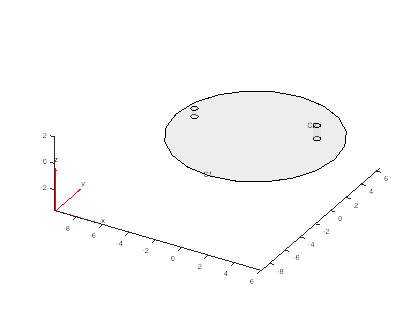

Imported_Geometry = importGeometry('2E 12mm Mesh.stl');

pdegplot(Imported_Geometry,'CellLabels','on','FaceAlpha',0.3);

pdegplot(Imported_Geometry,'EdgeLabels','on','FaceAlpha',.3);
Imported_Geometry = addFace(Imported_Geometry,3)

Imported_Geometry =   DiscreteGeometry with properties:

       NumCells: 3
       NumFaces: 9
       NumEdges: 6
    NumVertices: 6
       Vertices: [6×3 double]


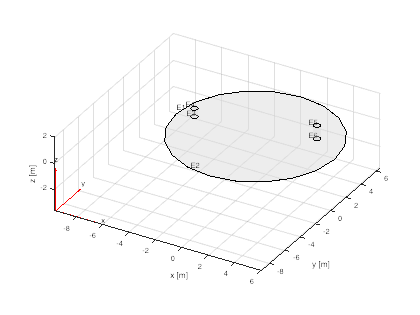


grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")

## Define Fluid Geometry

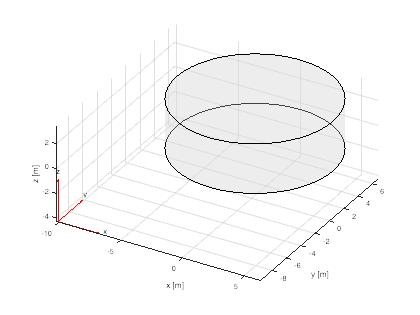

%First plot geometry and adjust the volume of the container of fluid then incorporate the
%geometry

gmFluid = multicylinder(6.3,4);

% Now align the fluid volume and the geometry to allow them to combine
gmFluid.translate([0,.5,-.5]);

pdegplot(gmFluid,'FaceAlpha',0.3);
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")

## Combine Fluid + Mesh and Electrode Geometries

%Ensure that the volume gmAir is the first input
gmModel = addCell(gmFluid,Imported_Geometry);
gmModel = scale(gmModel,.001); %scaled from mm to m

### Initial Plot of Loaded Geometry

Change the FaceAlpa input in pdegplot to better view the face and edge lables of the geometry.

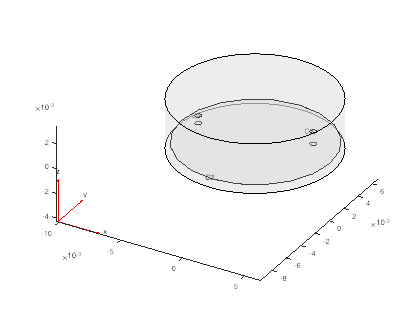

pdegplot(gmModel,'CellLabels','on','FaceAlpha',.3);

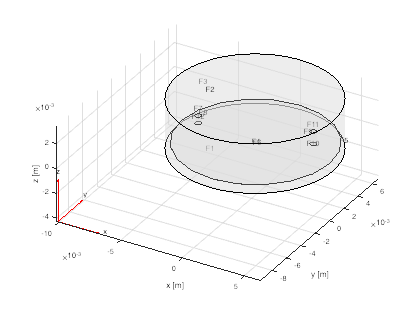

pdegplot(gmModel,'FaceLabels','on','FaceAlpha',.3);
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")

### Assign The Geomtery to the Model

The defined geometry becomes set to the model handle. The model is created and defined as Estat_model which is also an N # of equation elliptic model. 

%Estat_model = createpde;
Estat_model = createpde("electromagnetic","electrostatic");
Estat_model.Geometry = gmModel;

## Create the Mesh

From this we can generate a mesh where the fineness is defined by Hmin value, set at .35 for the lowest fideltiy model and Hmax at 1.5 for high fidelity models. The mesh then gets assigned to the Estat_model.

mesh = generateMesh(Estat_model,'Hmin', .0001);

The mesh can then be visualized for completeness and accuracy

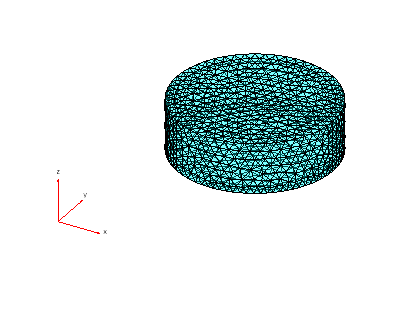

pdemesh(Estat_model,'FaceAlpha',.3)

The sizing of the mesh and geometery can be calculated by measuring the max distance between nodes in each direction. This value should be consistent with the dimensions of the geometry that was uploaded. 

% Measuring the dimesions of the mesh
xLength = max(Estat_model.Mesh.Nodes(1,:)) - min(Estat_model.Mesh.Nodes(1,:))

xLength = 0.0126

yLength = max(Estat_model.Mesh.Nodes(2,:)) - min(Estat_model.Mesh.Nodes(2,:))

yLength = 0.0126

zLength = max(Estat_model.Mesh.Nodes(3,:)) - min(Estat_model.Mesh.Nodes(3,:))

zLength = 0.0040

# Electrostatic Field Analysis

## Define Governing PDE (Poisson Equation)

−∇⋅(*ϵ*∇*V*)=*ρ*

where *ϵ* is the coefficient of permittivity and *ρ* is the charge density. The coefficient of permittivity does not affect the result in this example as long as the coefficient is constant. Assuming that there is no charge in the domain, you can simplify the Poisson equation to the Laplace equation,

Δ*V*=0.

### Specify Coefficients

%specifyCoefficients(Estat_model,'m',0,'d',0,'c',1,'a',0,'f',0);

## Boundary Conditions and Variable Deffinitions

Boundary conditions are assigned to the working and counter electrode surfaces, as well as the mesh surface. The working electrode is the active electrode to which the voltage wave form is applied. The culture media has its own conductivity and permitivity,

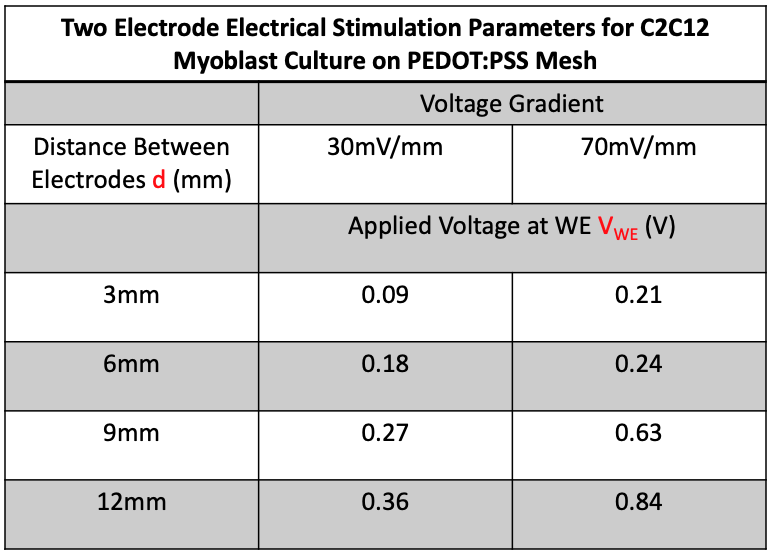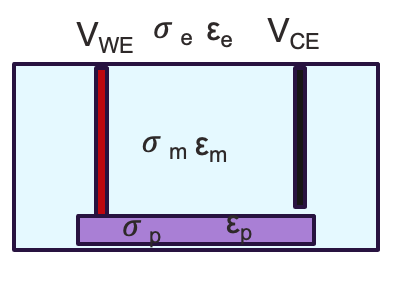

## Variable Definitions

These parameters are defined to represent the characteristics of the electrolyte solution and the material properties

% Dielectric Constant
epsilon_CE = 1;
epsilon_WE = 1;
%epsilon_RE = 10000;

epsilon_S = 41838;
epsilon_CM = 80; 

% Conductivity
sigma_CE = 9.43E6;
sigma_WE = 9.43E6;
%sigma_RE = 10000;

sigma_S = 23;
sigma_CM = 1.5; 

### Establish Time Domain of Simulation 

tlist = linspace(0,2,10);

### Define Conditions of the Numerical Simulation

### First identify the relevant faces of the analysis on the geometry

pdegplot(gmModel,'CellLabels','on','FaceAlpha',.3);

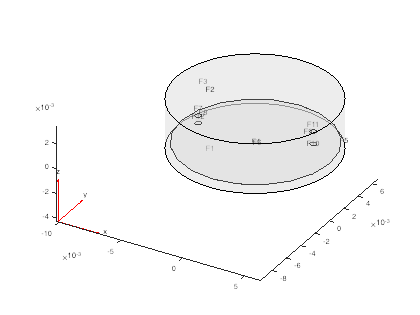


pdegplot(gmModel,'FaceLabels','on','FaceAlpha',.3);

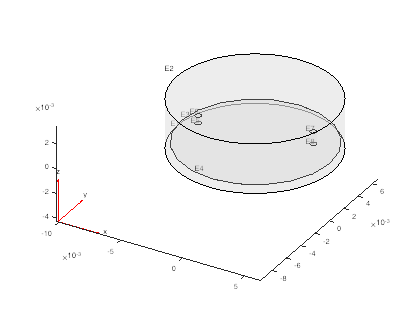

pdegplot(gmModel,'EdgeLabels','on','FaceAlpha',.3);


Fluid_Cell = 1;
%Fluid_Faces = cellFaces(gmModel,Fluid_Cell);
Fluid_Faces = [1 2 3];
%Fluid_Edges = cellEdges(gmModel,Fluid_Cell);

Scaffold_Cell = 2;
Scaffold_Faces = cellFaces(gmModel,Scaffold_Cell);
Scaffold_Edges = cellEdges(gmModel,Scaffold_Cell);

CE_Cell = 3;
CE_Faces = cellFaces(gmModel,CE_Cell);
CE_Edges = cellEdges(gmModel,CE_Cell);

WE_Cell = 4;
WE_Faces = cellFaces(gmModel,WE_Cell);
WE_Edges = cellEdges(gmModel,WE_Cell);

WE_Contact_Faces = 12;
% WE_Contact_Edge = 5;
% 
% RE_Cell = 4;
% RE_Faces = cellFaces(gmModel,RE_Cell);
% RE_Edges = cellEdges(gmModel,RE_Cell);

## Material Properties  

The materials of interest are the electrolyte medium or culture medium, scaffold polymer material and dopant, working electrode material.

First make necessary unit conversions to match the units expected from matlab

Define permeability and permittivity values as perscribed for the fluid volume.

%%Vacuum
Estat_model.VacuumPermeability = 1.2566370614E-6; %H/m (Henry per meter)
Estat_model.VacuumPermittivity = 8.8541878128E-12; %F/m (Farads per meter)


% %%Working Electrode
electromagneticProperties(Estat_model,"Cell", ...
    WE_Cell,"RelativePermittivity",epsilon_WE,"Conductivity",sigma_WE)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 4
    RelativePermittivity: 1
    RelativePermeability: []
            Conductivity: 9430000


%%Counter Electrode
electromagneticProperties(Estat_model,"Cell", ...
    CE_Cell,"RelativePermittivity",epsilon_CE,"Conductivity",sigma_CE)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 3
    RelativePermittivity: 1
    RelativePermeability: []
            Conductivity: 9430000



%Scaffold
electromagneticProperties(Estat_model,"Cell", ...
    Scaffold_Cell,"RelativePermittivity",epsilon_S,"Conductivity",sigma_S)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 2
    RelativePermittivity: 41838
    RelativePermeability: []
            Conductivity: 23


%%Culture Medium
electromagneticProperties(Estat_model,"Cell", ...
    Fluid_Cell,"RelativePermittivity",epsilon_CM,"Conductivity",sigma_CM)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 1
    RelativePermittivity: 80
    RelativePermeability: []
            Conductivity: 1.5000




% %Reference Electrode
% electromagneticProperties(Estat_model,"Cell", ...
%     RE_Cell,"RelativePermittivity",epsilon_RE,"Conductivity",sigma_RE)

## Boundary Conditions

In the pHEMA paper the conductivity of these scaffolds was tested using a custome ITO dual electrode setup. The boundary conditions of the faces that make contact with this electrode setup are set to be constant voltages.

% Potential Values
Plate_Voltage = 0;
WE_Voltage = .5;
CE_Voltage = 0;
RE_Voltage = 0;

%%Well Wall Conditions
%electromagneticBC(Estat_model,'Face',Fluid_Faces,'Voltage',0);

%%Working Electrode Conditions
electromagneticBC(Estat_model,'Face',WE_Faces,'Voltage',WE_Voltage);

%%Counter Electrode Conditions
electromagneticBC(Estat_model,'Face',CE_Faces,'Voltage',CE_Voltage);

% %%Fluid Conditions
% electromagneticBC(Estat_model,'Face',_Faces,'Voltage',Electrode_Face_Voltage)

% %%RE Conditions
% electromagneticBC(Estat_model,'Face',RE_Faces,'Voltage',RE_Voltage)

## Charge Density

%% Charge Densities
WE_CD = 2.6E-5;
% CE_CD = 0;
% RE_CD = 0;
% %S_CD = 2.5E-5;
% F_CD = 15E-7;

%% Current Densities
% WE_CD = 4.6;
% CE_CD = 0;
% RE_CD = 0;
% S_CD = 0;
% F_CD = 0;

%% Working Electrode
%electromagneticSource(Estat_model, "ChargeDensity",WE_CD,"Cell", WE_Cell);

% %% Counter Electrode
% electromagneticSource(Estat_model,"Cell",CE_Cell, "ChargeDensity",WE_CD);

% %% Fluid
%electromagneticSource(Estat_model,"Cell",Fluid_Cell, "ChargeDensity",F_CD);

% %% Refference Electrode
% electromagneticSource(Estat_model,"Cell",Scaffold_Cell, "ChargeDensity",WE_CD);

% %% Scaffold
% electromagneticSource(Estat_model,"Cell",Scaffold_Cell, "ChargeDensity",S_CD);

## Solving the Model

emagmodel = Estat_model;
R = solve(emagmodel);
model = emagmodel;

## Visualizing Model Results

### Selecting Subdomains for Plotting

S_mesh = findElements(model.Mesh,"Region","Cell",Scaffold_Cell);
F_mesh = findElements(model.Mesh,"Region","Cell",Fluid_Cell);
CE_mesh = findElements(model.Mesh,"Region","Cell",CE_Cell);
WE_mesh = findElements(model.Mesh,"Region","Cell",WE_Cell);
% RE_mesh = findElements(model.Mesh,"Region","Cell",RE_Cell);

### Electric Potential Plot

Plot of the electric field and distribuiton throughout the geometery. Be sure to adjust opacity of the plot to see features.

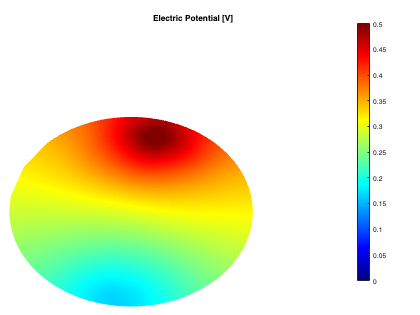

%Scaffold
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh), ...
          "ColorMapData",R.ElectricPotential);

title('Electric Potential [V]')
xlim([-0.0078 0.0039])
ylim([-0.00177 0.00832])
zlim([0.00108 0.00471])
view([-259.52293 51.15699])

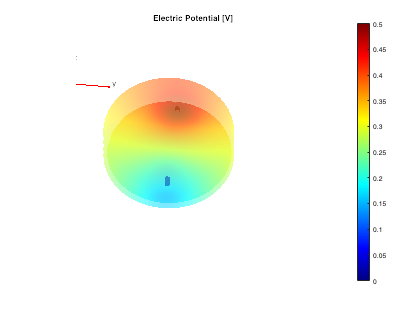



%Fluid
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,F_mesh), ...
          "ColorMapData",R.ElectricPotential,"FaceAlpha",.3);

title('Electric Potential [V]')
xlim([-0.0122 0.0111])
ylim([-0.0073 0.0128])
zlim([-0.00408 0.00315])
view([-264.17392 54.67524])


% pdeplot3D(model.Mesh.Nodes, ...
%           model.Mesh.Elements(:,RE_mesh), ...
%           "ColorMapData",R.ElectricPotential,"FaceAlpha",.5);
% 
% title('Voltage [V]')
% xlabel('x')
% ylabel('y')
% zlabel('z')
% axis equal

### Electric Field Plot 

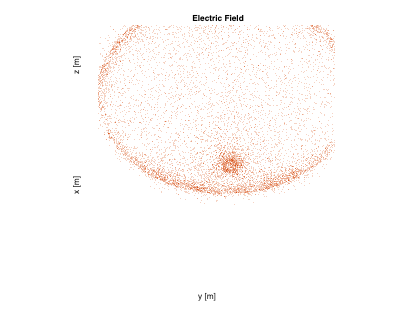

%Scaffold 
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh) ...
          ,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez])
axis equal

title('Electric Field')
grid on
xlabel("x [m]",'Visible','on')
ylabel("y [m]",'Visible','on')
zlabel("z [m]", 'Visible','on')

xlim([-0.0042 0.0075])
ylim([-0.00427 0.00582])
zlim([-0.00808 -0.00445])
view([-95.76331 50.82417])

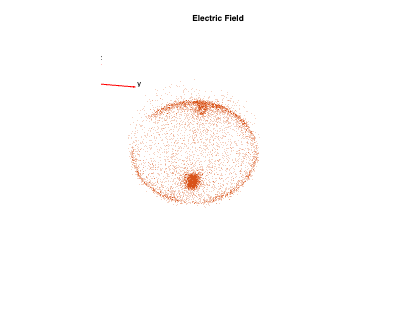




%Fluid
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,F_mesh) ...
          ,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez])

title('Electric Field')
axis equal
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")

xlim([-0.0122 0.0111])
ylim([-0.0073 0.0128])
zlim([-0.00408 0.00315])
view([-264.17392 54.67524])

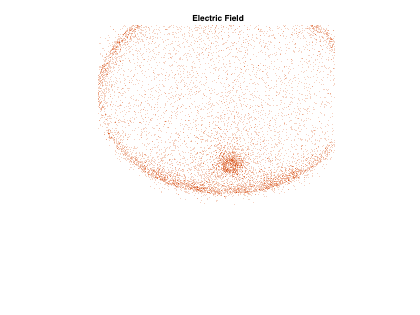


%CE
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,CE_mesh) ...
          ,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez])

title('Electric Field')
axis equal
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")

xlim([-0.0042 0.0075])
ylim([-0.00427 0.00582])
zlim([-0.00808 -0.00445])
view([-95.76331 50.82417])

### Electric Flux Density Plot

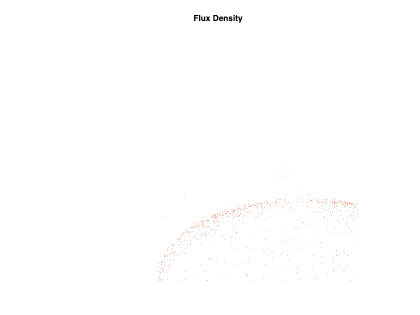

%Scaffold
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh), ...
          "FlowData",[R.ElectricFluxDensity.Dx ...
          R.ElectricFluxDensity.Dy ...
          R.ElectricFluxDensity.Dz],'Mesh','on',"FaceAlpha", 1)
title('Flux Density')
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")

axis equal
xlim([0.0012 0.0141])
ylim([-0.0017 0.0094])
zlim([-0.00072 0.00328])
view([-91.92556 32.54789])

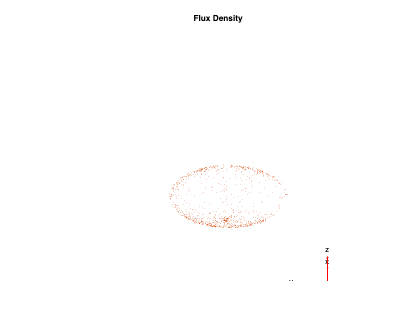


%Fluid
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,F_mesh), ...
          "FlowData",[R.ElectricFluxDensity.Dx ...
          R.ElectricFluxDensity.Dy ...
          R.ElectricFluxDensity.Dz],'Mesh','on')
title('Flux Density')
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
axis equal

xlim([-0.0113 0.0214])
ylim([-0.0147 0.0180])
zlim([-0.00298 0.00741])
view([-90.09855 32.30302])


%Electrodes
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,CE_mesh), ...
          "FlowData",[R.ElectricFluxDensity.Dx ...
          R.ElectricFluxDensity.Dy ...
          R.ElectricFluxDensity.Dz])
title('Flux Density')
grid on
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
axis equal

xlim([0.0012 0.0141])
ylim([-0.0017 0.0094])
zlim([-0.00072 0.00328])
view([-91.92556 32.54789])

# Electrochemical Field Analysis

## Generate Echem PDE and Assign Geometry

Echem_model = createpde;
Echem_model.Geometry = gmModel;